% Clearing the work space
 clear;
 clc;
 warning('off');

data_loc = "C:\Users\Dell\Documents\MATLAB\Mydata\train";

dt = datastore(data_loc,'IncludeSubfolders',true,"LabelSource","foldernames");

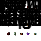

figure;
perm = randperm(16000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(dt.Files{perm(i)});
    title(dt.Labels(perm(i)), 'Interpreter', 'none');
end


labelCount = countEachLabel(dt)

labelCount = 11×2 table
      Label       Count
    __________    _____

    Banana        1500 
    Cherry        1500 
    Kiwi          1500 
    Lemon         1500 
    Mango         1500 
    Orange        1500 
    Peach         1500 
    Plum          1500 
    Raspberry     1500 
    Strawberry    1500 
    Watermelon    1500 


input_size = [100,100,3];


[dtTrain,dtValidation,dtTest] = splitEachLabel(dt,0.7,0.15,'randomized');


pixelRange = [-3 3];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-20,20], ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

augtrain = augmentedImageDatastore(input_size,dtTrain,'ColorPreprocessing','gray2rgb','DataAugmentation',imageAugmenter);
% We don't need to augment the validation test
augValidation = augmentedImageDatastore(input_size,dtValidation,'ColorPreprocessing','gray2rgb','DataAugmentation',imageAugmenter);
augtest = augmentedImageDatastore(input_size,dtTest,'ColorPreprocessing','gray2rgb');

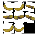

% Get a few example augmented images from the datastore
numExamples = 1;
exampleData = preview(augtrain);
exampleImages = exampleData.input(:,:,:,1:numExamples);
exampleLabels = exampleData.input(1:numExamples);

% Display the example images with their descriptions
figure
montage(exampleImages);
title('Example Augmented Images');



layers = [
% Image Input Layer An imageInputLayer 
    imageInputLayer(input_size,"Name","imageinput","Normalization","zerocenter")

    % Convolutional Layer 
convolution2dLayer(3,8,'Padding','same')

% Batch Normalization 
    batchNormalizationLayer

% ReLU Layer The batch
    reluLayer

% Max Pooling Layer  
    % More values means less weights
    maxPooling2dLayer(3,'Stride',4)
    %------------------------------
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(4,'Stride',5)
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer

% Fully Connected Layer (Number of Classes) 
    fullyConnectedLayer(11)

% Softmax Layer 
    softmaxLayer

% Classification Layer The final layer 
 classificationLayer];


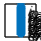

%% 
%plot(lgraph) plots a diagram of the layer graph lgraph. 
% The plot function labels each layer by its name and displays all 
% layer connections.

lgraph = layerGraph(layers);
figure
plot(lgraph);


options = trainingOptions('sgdm', 'Momentum',0.85,...
 'InitialLearnRate',0.01, ...
 'MaxEpochs',4, ...
 'Shuffle','every-epoch', ...
 'ValidationData',augValidation, ...
 'ValidationFrequency',30, ...
 'Verbose',true, ...
 'Plots','training-progress');

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |       13.28% |        8.16% |       2.6982 |       2.7683 |          0.0100 |
|       1 |          30 |       00:00:16 |       82.81% |       81.25% |       0.9511 |       0.9686 |          0.0100 |
|       1 |          50 |       00:00:21 |       89.06% |              |       0.4755 |              |          0.0100 |
|       1 |          60 |       00:00:26 |       95.31% |       93.98% |       0.3325 |   

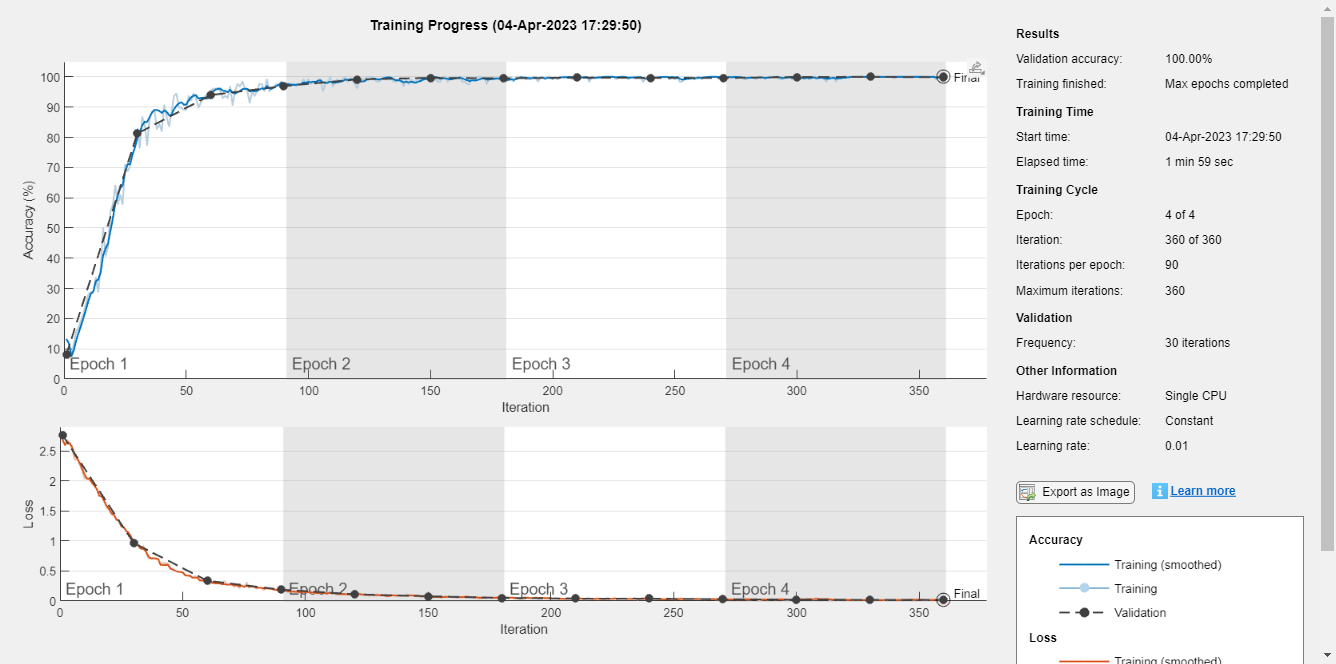

net = trainNetwork(augtrain,layers,options);


YPred = classify(net,augtest);

Unrecognized function or variable 'net'.

YTest = dtTest.Labels;
accuracy = sum(YPred == YTest)/numel(YTest)
%confusion matrix
YPred1 = classify(net,augValidation);
Yvalidation = dtValidation.Labels;
plotconfusion(YPred1,Yvalidation)
%% % Display sample images and their predicted labels

% Display sample images and their predicted labels
numImages = 20;
figure
for i = 1:numImages
    % Read a random testing image
    idx = randi(numel(augtest.Files));
    I = readimage(dtTest, idx);
    
    % Make a prediction
    label = YPred(idx);
    
    % Display the image and predicted label
    subplot(5, 5, i);
    imshow(I);
    title(char(label));
end